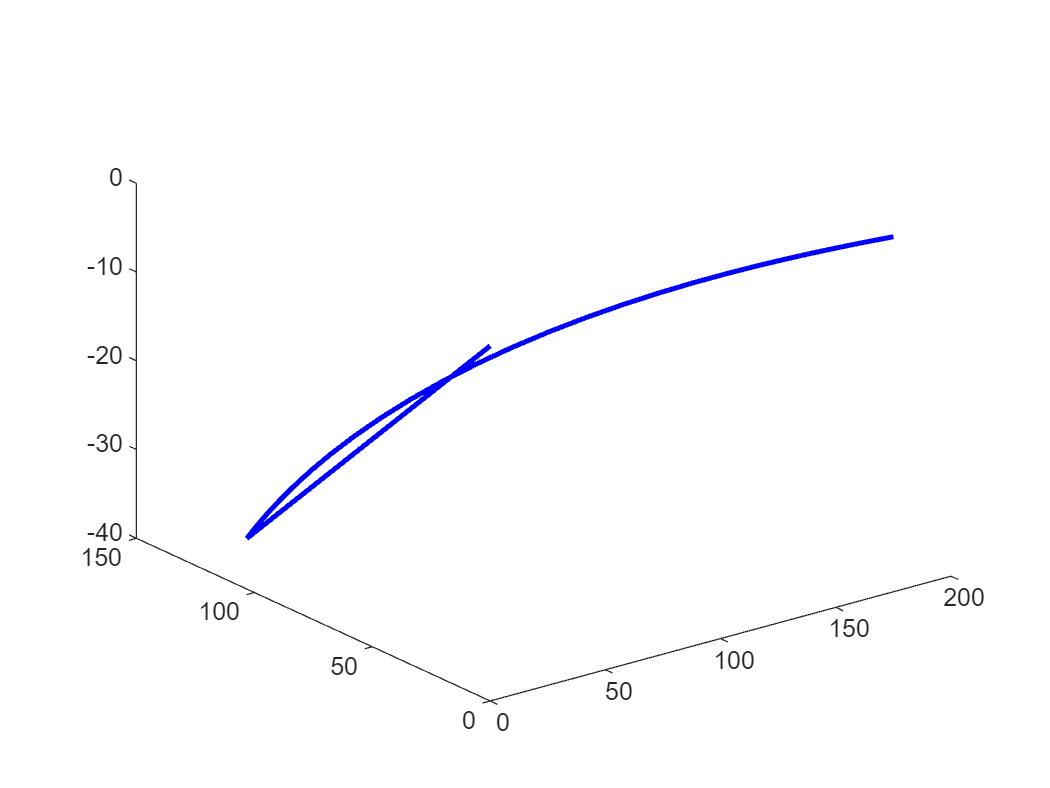

clc
clear

L1 = 75;
L2 = 100;

px = [175 30.086];
py = [0   132.597];
pz = [0   -39.999];

n = length(px);
theta1 = zeros(n,1);
theta2 = zeros(n,1);
d3 = zeros(n,1);

for i = 1 : n
%%%%%%%%%%%%%%%%%%% Cinemática_Inversa %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% theta_1 %%%
    d = sqrt(px(1,i)^2 + py(1,i)^2);
    beta = atan2d(py(1,i),px(1,i));
    Ca = (L1^2 + d^2 - L2^2)/(2*L1*d);
    Sap = sqrt(1 - Ca^2);

    alpha_p = atan2d(Sap,Ca);
    
    theta1(i,1) = beta - alpha_p;
    
    %%% theta_2 %%%
    C2 = (d^2 - L1^2 - L2^2)/(2*L1*L2);
    S2p = sqrt(1 - C2^2);
    S2n = -sqrt(1 - C2^2);
    
    theta2(i,1) = atan2d(S2p,C2);
    
    %%% d3 %%%%%
    d3(i,1) = pz(1,i);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

end

theta1_i = theta1(1,1);
theta1_f = theta1(2,1);

theta2_i = theta2(1,1);
theta2_f = theta2(2,1);

d3_i = d3(1,1);
d3_f = d3(2,1);

tf = 3;
t = 0: 0.1: tf;
k = length(t);

theta1_t = zeros(k,1);
theta2_t = zeros(k,1);
d3_t = zeros(k,1);

theta1p_t = zeros(k,1);
theta1pp_t = zeros(k,1);

theta11 = zeros(k,1);
theta11p = zeros(k,1);
theta11pp = zeros(k,1);

theta2p_t = zeros(k,1);
theta2pp_t = zeros(k,1);

theta22 = zeros(k,1);
theta22p = zeros(k,1);
theta22pp = zeros(k,1);

d3p_t = zeros(k,1);
d3pp_t = zeros(k,1);

d33 = zeros(k,1);
d33p = zeros(k,1);
d33pp = zeros(k,1);

for j = 1 : k

    %%% Interpolador_Articulación_1 %%%%%%
    a0_1 = theta1_i;
    a1_1 = 0;
    a2_1 = 3*(theta1_f - theta1_i)/(tf^2);
    a3_1 = -2*(theta1_f - theta1_i)/(tf^3);
    
    theta1_t(j,1) = a0_1 + a1_1*t(j) + a2_1*(t(j))^2 + a3_1*(t(j))^3;
    theta1p_t(j,1) = a1_1 + 2*a2_1*t(j) + 3*a3_1*(t(j))^2;
    theta1pp_t(j,1) = 2*a2_1 + 6*a3_1*t(j);


    %%% Interpolador_Articulación_2 %%%%%%
    a0_2 = theta2_i;
    a1_2 = 0;
    a2_2 = 3*(theta2_f - theta2_i)/(tf^2);
    a3_2 = -2*(theta2_f - theta2_i)/(tf^3);
    
    theta2_t(j,1) = a0_2 + a1_2*t(j) + a2_2*(t(j))^2 + a3_2*t((j))^3;
    theta2p_t(j,1) = a1_2 + 2*a2_2*t(j) + 3*a3_2*(t(j))^2;
    theta2pp_t(j,1) = 2*a2_2 + 6*a3_2*t(j);

    
    %%% Interpolador_Articulación_3 %%%%%%
    a0_3 = d3_i;
    a1_3 = 0;
    a2_3 = 3*(d3_f - d3_i)/(tf^2);
    a3_3 = -2*(d3_f - d3_i)/(tf^3);
    
    d3_t(j,1) = a0_3 + a1_3*t(j) + a2_3*(t(j))^2 + a3_3*t((j))^3;
    d3p_t(j,1) = a1_3 + 2*a2_3*t(j) + 3*a3_3*(t(j))^2;
    d3pp_t(j,1) = 2*a2_3 + 6*a3_3*t(j);

end

% subplot(3,3,1)
% plot(t,theta1_t,'g',LineWidth=2)
% subplot(3,3,4)
% plot(t,theta1p_t,'b',LineWidth=2)
% subplot(3,3,7)
% plot(t,theta1pp_t,'b',LineWidth=2)
% 
% 
% subplot(3,3,2)
% plot(t,theta2_t,'g',LineWidth=2)
% subplot(3,3,5)
% plot(t,theta2p_t,'b',LineWidth=2)
% subplot(3,3,8)
% plot(t,theta2pp_t,'b',LineWidth=2)
% 
% 
% subplot(3,3,3)
% plot(t,d3_t,'g',LineWidth=2)
% subplot(3,3,6)
% plot(t,d3p_t,'b',LineWidth=2)
% subplot(3,3,9)
% plot(t,d3pp_t,'b',LineWidth=2)




for l = 1 : k

    px(l,1) = L1*cosd(theta1_t(l,1)) + L2*cosd(theta1_t(l,1) + theta2_t(l,1));
    py(l,1) = L1*sind(theta1_t(l,1)) + L2*sind(theta1_t(l,1) + theta2_t(l,1));
    pz(l,1) = d3_t(l,1);

end

plot3(px,py,pz,'b',LineWidth=2)